clc
clear
close all

%% Create trajectory for From Workspace blocks
Ts = 0.05;
t_end = 180;
t = (0:Ts:t_end)';

x_max = 80000;
h_max = 20000;

x_true_traj = linspace(0, x_max, length(t))';
s = x_true_traj / x_max;
y_true_traj = 4 * h_max * s .* (1 - s);

x_ts = timeseries(x_true_traj, t);
y_ts = timeseries(y_true_traj, t);

%% Monte Carlo settings
Nmc = 50;   % use 1 for trajectory/error example, 50 for final Monte Carlo results

rmse_kf_all       = zeros(Nmc,1);
rmse_ukf_r_all    = zeros(Nmc,1);
rmse_ukf_ir_all   = zeros(Nmc,1);
rmse_ukf_full_all = zeros(Nmc,1);

%% Store one example run for plotting
example_run = 1;

t_example = [];

x_true_example = [];
y_true_example = [];

x_kf_example = [];
y_kf_example = [];

x_ukf_r_example = [];
y_ukf_r_example = [];

x_ukf_ir_example = [];
y_ukf_ir_example = [];

x_ukf_full_example = [];
y_ukf_full_example = [];

epos_kf_example = [];
epos_ukf_r_example = [];
epos_ukf_ir_example = [];
epos_ukf_full_example = [];

for k = 1:Nmc

    %% Change random seeds for each run
    seed_radar_range   = 100 + k;
    seed_radar_bearing = 200 + k;
    seed_ir            = 300 + k;
    seed_ac            = 400 + k;

    %% Run simulation
    simOut = sim("new_fusion_model", "SrcWorkspace", "current");

    %% Extract truth
    t_sim  = simOut.x_true.Time(:);
    x_true = simOut.x_true.Data(:);
    y_true = simOut.y_true.Data(:);

    %% Extract KF
    x_kf = simOut.x_hat_kf.Data(:);
    y_kf = simOut.y_hat_kf.Data(:);

    %% Extract UKF variants
    x_ukf_r = simOut.x_hat_ukf_r.Data(:);
    y_ukf_r = simOut.y_hat_ukf_r.Data(:);

    x_ukf_ir = simOut.x_hat_ukf_ir.Data(:);
    y_ukf_ir = simOut.y_hat_ukf_ir.Data(:);

    x_ukf_full = simOut.x_hat_ukf_full.Data(:);
    y_ukf_full = simOut.y_hat_ukf_full.Data(:);

    %% Safe length matching
    N_all = min([length(t_sim), length(x_true), length(y_true), ...
                 length(x_kf), length(y_kf), ...
                 length(x_ukf_r), length(y_ukf_r), ...
                 length(x_ukf_ir), length(y_ukf_ir), ...
                 length(x_ukf_full), length(y_ukf_full)]);

    t_sim = t_sim(1:N_all);

    x_true = x_true(1:N_all);
    y_true = y_true(1:N_all);

    x_kf = x_kf(1:N_all);
    y_kf = y_kf(1:N_all);

    x_ukf_r = x_ukf_r(1:N_all);
    y_ukf_r = y_ukf_r(1:N_all);

    x_ukf_ir = x_ukf_ir(1:N_all);
    y_ukf_ir = y_ukf_ir(1:N_all);

    x_ukf_full = x_ukf_full(1:N_all);
    y_ukf_full = y_ukf_full(1:N_all);

    %% Position error magnitude
    epos_kf = sqrt((x_kf - x_true).^2 + (y_kf - y_true).^2);

    epos_ukf_r = sqrt((x_ukf_r - x_true).^2 + ...
                      (y_ukf_r - y_true).^2);

    epos_ukf_ir = sqrt((x_ukf_ir - x_true).^2 + ...
                       (y_ukf_ir - y_true).^2);

    epos_ukf_full = sqrt((x_ukf_full - x_true).^2 + ...
                         (y_ukf_full - y_true).^2);

    %% RMSE
    rmse_kf_all(k)       = sqrt(mean(epos_kf.^2));
    rmse_ukf_r_all(k)    = sqrt(mean(epos_ukf_r.^2));
    rmse_ukf_ir_all(k)   = sqrt(mean(epos_ukf_ir.^2));
    rmse_ukf_full_all(k) = sqrt(mean(epos_ukf_full.^2));

    %% Store one example run for plotting
    if k == example_run
        t_example = t_sim;

        x_true_example = x_true;
        y_true_example = y_true;

        x_kf_example = x_kf;
        y_kf_example = y_kf;

        x_ukf_r_example = x_ukf_r;
        y_ukf_r_example = y_ukf_r;

        x_ukf_ir_example = x_ukf_ir;
        y_ukf_ir_example = y_ukf_ir;

        x_ukf_full_example = x_ukf_full;
        y_ukf_full_example = y_ukf_full;

        epos_kf_example = epos_kf;
        epos_ukf_r_example = epos_ukf_r;
        epos_ukf_ir_example = epos_ukf_ir;
        epos_ukf_full_example = epos_ukf_full;
    end

    fprintf('Run %d / %d complete\n', k, Nmc);
end

Run 1 / 50 complete
Run 2 / 50 complete
Run 3 / 50 complete
Run 4 / 50 complete
Run 5 / 50 complete
Run 6 / 50 complete
Run 7 / 50 complete
Run 8 / 50 complete
Run 9 / 50 complete
Run 10 / 50 complete
Run 11 / 50 complete
Run 12 / 50 complete
Run 13 / 50 complete
Run 14 / 50 complete
Run 15 / 50 complete
Run 16 / 50 complete
Run 17 / 50 complete
Run 18 / 50 complete
Run 19 / 50 complete
Run 20 / 50 complete
Run 21 / 50 complete
Run 22 / 50 complete
Run 23 / 50 complete
Run 24 / 50 complete
Run 25 / 50 complete
Run 26 / 50 complete
Run 27 / 50 complete
Run 28 / 50 complete
Run 29 / 50 complete
Run 30 / 50 complete
Run 31 / 50 complete
Run 32 / 50 complete
Run 33 / 50 complete
Run 34 / 50 complete
Run 35 / 50 complete
Run 36 / 50 complete
Run 37 / 50 complete
Run 38 / 50 complete
Run 39 / 50 complete
Run 40 / 50 complete
Run 41 / 50 complete
Run 42 / 50 complete
Run 43 / 50 complete
Run 44 / 50 complete
Run 45 / 50 complete
Run 46 / 50 complete
Run 47 / 50 complete
Run 48 / 50 complete
R


%% Monte Carlo summary statistics
mean_kf   = mean(rmse_kf_all);
mean_r    = mean(rmse_ukf_r_all);
mean_ir   = mean(rmse_ukf_ir_all);
mean_full = mean(rmse_ukf_full_all);

std_kf   = std(rmse_kf_all);
std_r    = std(rmse_ukf_r_all);
std_ir   = std(rmse_ukf_ir_all);
std_full = std(rmse_ukf_full_all);

means = [mean_kf; mean_r; mean_ir; mean_full];
stds  = [std_kf; std_r; std_ir; std_full];

methods = {'KF'; 'UKF Radar'; 'UKF Radar + IR'; 'UKF Radar + IR + AC'};

%% Improvement relative to KF
improvement_vs_kf = (mean_kf - means) ./ mean_kf * 100;
improvement_vs_kf(1) = NaN;

%% Print summary
fprintf('\nRMSE Summary:\n');


RMSE Summary:


fprintf('KF: mean = %.3f m, std = %.3f m\n', mean_kf, std_kf);

KF: mean = 132.369 m, std = 4.808 m


fprintf('UKF radar: mean = %.3f m, std = %.3f m\n', mean_r, std_r);

UKF radar: mean = 90.765 m, std = 6.076 m


fprintf('UKF radar + IR: mean = %.3f m, std = %.3f m\n', mean_ir, std_ir);

UKF radar + IR: mean = 60.689 m, std = 3.516 m


fprintf('UKF radar + IR + AC: mean = %.3f m, std = %.3f m\n', mean_full, std_full);

UKF radar + IR + AC: mean = 61.031 m, std = 3.412 m



%% Summary table
RMSE_Summary_Table = table(methods, means, stds, improvement_vs_kf, ...
    'VariableNames', {'Method', 'Mean_RMSE_m', 'Std_RMSE_m', 'Improvement_vs_KF_percent'});

disp(RMSE_Summary_Table);

            Method             Mean_RMSE_m    Std_RMSE_m    Improvement_vs_KF_percent
    _______________________    ___________    __________    _________________________

    {'KF'                 }      132.37         4.8078                  NaN          
    {'UKF Radar'          }      90.765         6.0756                31.43          
    {'UKF Radar + IR'     }      60.689         3.5161               54.152          
    {'UKF Radar + IR + AC'}      61.031         3.4122               53.893          




%% Per-run RMSE table
Per_Run_RMSE_Table = table((1:Nmc)', rmse_kf_all, rmse_ukf_r_all, ...
    rmse_ukf_ir_all, rmse_ukf_full_all, ...
    'VariableNames', {'Run', 'KF', 'UKF_Radar', 'UKF_Radar_IR', 'UKF_Full'});

disp('RMSE values for each run:')

RMSE values for each run:


disp(Per_Run_RMSE_Table)

    Run      KF      UKF_Radar    UKF_Radar_IR    UKF_Full
    ___    ______    _________    ____________    ________

     1     134.12     92.896         60.581         61.16 
     2     128.51     85.037         65.548        63.586 
     3     127.79     85.475          61.49        61.704 
     4     128.81     84.722         55.328        55.249 
     5     138.12     96.702         53.548        53.538 
     6     128.41     85.033         63.306        63.664 
     7     136.21     96.298         61.261        60.668 
     8     125.22     82.507         70.298        71.236 
     9     143.53     100.35         60.608        61.844 
    10     137.11     98.293         61.311        62.796 
    11     134.05     91.116          58.83        59.102 
    12     127.22     84.081         61.565        60.799 
   

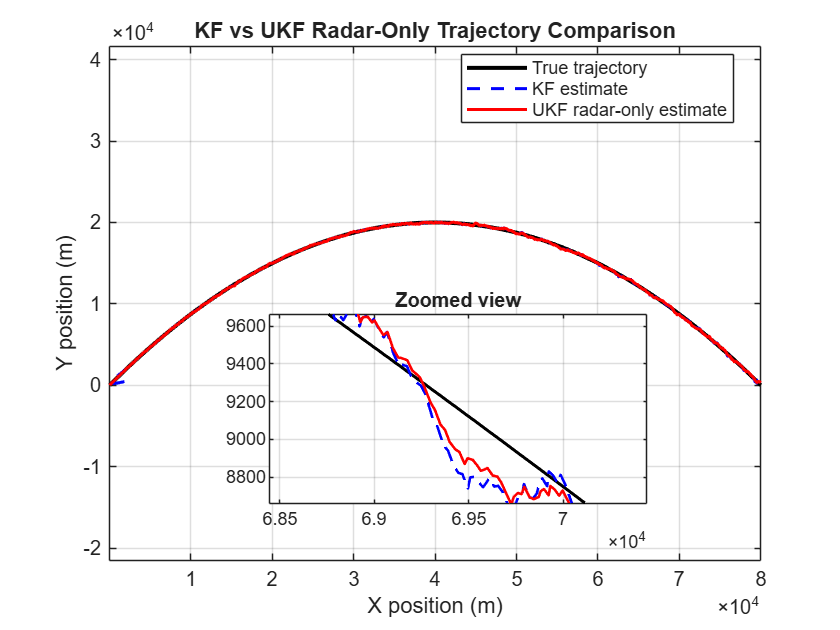


%% Find zoom region after initial transient and before final descent/end

t_start_ignore = 10;    % ignore first 10 s
t_end_ignore   = 20;    % ignore last 20 s

idx_valid = find(t_example >= t_start_ignore & t_example <= (t_example(end) - t_end_ignore));

[~, idx_local] = max(epos_kf_example(idx_valid));
idx_zoom = idx_valid(idx_local);

x_center = x_true_example(idx_zoom);
y_center = y_true_example(idx_zoom);

x_window = 1000;   
y_window = 500;

figure

% Main full trajectory plot
plot(x_true_example, y_true_example, 'k', 'LineWidth', 2)
hold on
plot(x_kf_example, y_kf_example, '--b', 'LineWidth', 1.5)
plot(x_ukf_r_example, y_ukf_r_example, '-r', 'LineWidth', 1.5)

grid on
axis equal
xlabel('X position (m)')
ylabel('Y position (m)')
title('KF vs UKF Radar-Only Trajectory Comparison')
legend('True trajectory', 'KF estimate', 'UKF radar-only estimate', ...
    'Location', 'best')

% Zoomed inset
axes('Position',[0.32 0.15 0.45 0.40])
box on

plot(x_true_example, y_true_example, 'k', 'LineWidth', 1.5)
hold on
plot(x_kf_example, y_kf_example, '--b', 'LineWidth', 1.3)
plot(x_ukf_r_example, y_ukf_r_example, '-r', 'LineWidth', 1.3)

grid on
axis equal
xlim([x_center - x_window, x_center + x_window])
ylim([y_center - y_window, y_center + y_window])
title('Zoomed view')


%% Figure 2: UKF sensor fusion trajectory comparison
%% UKF fusion trajectory with zoomed inset

% Ignore start and end
t_start_ignore = 10;   
t_end_ignore   = 20;   

idx_valid = find(t_example >= t_start_ignore & ...
                 t_example <= (t_example(end) - t_end_ignore));

% Difference between radar-only UKF and full-fusion UKF
fusion_sep = sqrt((x_ukf_r_example - x_ukf_full_example).^2 + ...
                  (y_ukf_r_example - y_ukf_full_example).^2);

[~, idx_local] = max(fusion_sep(idx_valid));
idx_zoom = idx_valid(idx_local);

x_center = x_true_example(idx_zoom);
y_center = y_true_example(idx_zoom);

x_window = 1000;
y_window = 500;

figure

% Main full trajectory plot
plot(x_true_example, y_true_example, 'k', 'LineWidth', 2)
hold on
plot(x_ukf_r_example, y_ukf_r_example, 'b', 'LineWidth', 1.5)
plot(x_ukf_ir_example, y_ukf_ir_example, 'g', 'LineWidth', 1.5)
plot(x_ukf_full_example, y_ukf_full_example, 'r', 'LineWidth', 1.5)

grid on
axis equal
xlabel('X position (m)')
ylabel('Y position (m)')
title('UKF Sensor Fusion Trajectory Comparison')
legend('True trajectory', 'UKF Radar', 'UKF Radar + IR', ...
    'UKF Radar + IR + AC', 'Location', 'best')

% Zoomed inset
axes('Position',[0.32 0.15 0.45 0.40])
box on

plot(x_true_example, y_true_example, 'k', 'LineWidth', 1.5)
hold on
plot(x_ukf_r_example, y_ukf_r_example, 'b', 'LineWidth', 1.3)
plot(x_ukf_ir_example, y_ukf_ir_example, 'g', 'LineWidth', 1.3)
plot(x_ukf_full_example, y_ukf_full_example, 'r', 'LineWidth', 1.3)

grid on
axis equal
xlim([x_center - x_window, x_center + x_window])
ylim([y_center - y_window, y_center + y_window])
title('Zoomed view')


%% Figure 3: Position error over time for example run
figure
plot(t_example, epos_kf_example, 'LineWidth', 1.5)
hold on
plot(t_example, epos_ukf_r_example, 'LineWidth', 1.5)
plot(t_example, epos_ukf_ir_example, 'LineWidth', 1.5)
plot(t_example, epos_ukf_full_example, 'LineWidth', 1.5)
grid on
xlabel('Time (s)')
ylabel('Position error magnitude (m)')
title(sprintf('Position Error Over Time (Example Run %d)', example_run))
legend('KF', 'UKF Radar', 'UKF Radar + IR', 'UKF Radar + IR + AC', ...
    'Location', 'best')


%% Figure 4: Mean RMSE with standard deviation error bars
figure
bar(means)
hold on
errorbar(1:4, means, stds, '.k', 'LineWidth', 1.5)
set(gca, 'XTickLabel', {'KF','UKF Radar','UKF R+IR','UKF Full'})
ylabel('Mean RMSE (m)')
title('Mean RMSE Comparison')
grid on


%% Figure 5: Optional RMSE variation across Monte Carlo runs
if Nmc > 1
    figure
    plot(rmse_kf_all, 'o-', 'LineWidth', 1.2)
    hold on
    plot(rmse_ukf_r_all, 'o-', 'LineWidth', 1.2)
    plot(rmse_ukf_ir_all, 'o-', 'LineWidth', 1.2)
    plot(rmse_ukf_full_all, 'o-', 'LineWidth', 1.2)
    grid on
    xlabel('Monte Carlo run')
    ylabel('RMSE (m)')
    title('RMSE Variation Across Monte Carlo Runs')
    legend('KF', 'UKF Radar', 'UKF Radar + IR', 'UKF Radar + IR + AC', ...
        'Location', 'best')
end